clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = 273.15+20;
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


n = param.n;

yalmip('clear')
gamma = sdpvar(1);
q = cell(1,param.n);
y = cell(1,param.n);
for i=1:param.n
    q{i} = sdpvar(3);
    y{i} = sdpvar(1,3,'full');
end
Q = blkdiag(q{:});
Y = blkdiag(y{:});

Cy = blkdiag([zeros(2,1), eye(2)],[zeros(2,1), eye(2)],[zeros(2,1), eye(2)],[zeros(2,1), eye(2)]);
% Setup constraint
constraints = [param.model.A * Q + Q * param.model.A.' + param.model.B_Bar * Y + Y.' * param.model.B_Bar.' <=0];
constraints = [constraints, [param.model.A * Q + Q * param.model.A.' + param.model.B * Y + Y.' * param.model.B.', param.model.B, Y.';
                param.model.B.', -gamma * eye(4), zeros(4,4);
                Y, zeros(4,4), -gamma * eye(4)] <= 0];
constraints = [constraints,  Q >= 0, gamma >= 0];
options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints, gamma, options);
value(gamma)

ans = 1.0203

K = value(Y)/value(Q);
Ksf = K

Ksf =    38.2376   -0.4178    2.3913         0         0         0         0         0         0         0         0         0
         0         0         0  233.5937    2.1296    7.1928         0         0         0         0         0         0
         0         0         0         0         0         0  252.0652    2.3531    7.7454         0         0         0
         0         0         0         0         0         0         0         0         0  217.2343    1.9737    6.5125



yalmip('clear')
p = cell(1,param.n);
for i=1:param.n
    p{i} = sdpvar(3);
end
P = blkdiag(p{:});
sigma = sdpvar(1);
constraints = (param.model.A + param.model.B*K).'*P + P*(param.model.A + param.model.B*K)<=0;
constraints = [constraints, param.model.A.'*P + P*param.model.A - sigma*(Cy.'*Cy) <= 0];
constraints = [constraints, P>=eye(12), sigma >= 0];
options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints, [], options);

P_min = value(P)

P_min =     8.1594   -3.0571    1.7876         0         0         0         0         0         0         0         0         0
   -3.0571    9.0629    5.9643         0         0         0         0         0         0         0         0         0
    1.7876    5.9643   25.7877         0         0         0         0         0         0         0         0         0
         0         0         0    1.9617   -0.7872    0.2009         0         0         0         0         0         0
         0         0         0   -0.7872    5.8723    3.5008         0         0         0         0         0         0
         0         0         0    0.2009    3.5008   15.2109         0         0         0         0         0         0
         0         0         0         0         0         0    1.8177   -0.7232    0.1793         0         0         0
         0         0         0         0         0         0   -0.7232    5.7296    3.3747         0         0         0
         0         0    


yalmip('clear')
f = cell(1,param.n);
for j=1:param.n
    f{j} = sdpvar(1,2,'full');
end
F = blkdiag(f{:});
gamma = sdpvar(1);

k = [F(:,1);F(:,2);F(:,3);F(:,4);F(:,5);F(:,6);F(:,7);F(:,8)];
constraints = [gamma, k.'; k, eye(size(k,1))]>=0;
constraints = [constraints, (param.model.A + param.model.B*F*Cy).'*P_min + P_min*(param.model.A + param.model.B*F*Cy)<=0];
% 
% A = [param.model.A, param.model.B, zeros(12,4);
%      zeros(4,12), -gamma/2*eye(4), zeros(4,4);
%      zeros(4,12), zeros(4,4), -gamma/2*eye(4)];
% B = [param.model.B; zeros(4,4); eye(4)];
% C = [blkdiag([zeros(2,1), eye(2)],[zeros(2,1), eye(2)],[zeros(2,1), eye(2)],[zeros(2,1), eye(2)]), zeros(8,4), zeros(8,4)];
% Q = eye(20);
% P_bar = blkdiag(P_min,eye(4),eye(4));
% constraints = [P_bar*B*F*C + (P_bar*B*F*C).' + A.'*P_bar + P_bar*A <= 0, gamma>=0];
options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints, gamma, options)

sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0758
       solvertime: 0.0062
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


F_min = value(F)

F_min =    10.6932    8.9426         0         0         0         0         0         0
         0         0   15.2248   19.4615         0         0         0         0
         0         0         0         0   20.7998   18.6451         0         0
         0         0         0         0         0         0   18.2976   19.4256


value(gamma)

ans = 2.2973e+03

-1.437279, -3.651392, 0.000000, -0.000000, 
-0.000000, -182.756679, 0.000000, -0.000000, 
-0.000000, -182.756679, 0.000000, -0.000000, 
-0.000000, -182.756679, 0.000000, -0.000000, 
-0.000000, -182.756679, 0.000000, -0.000000, 
-0.000000, -182.756679, 0.000000, -0.000000, 
-0.000000, -182.756679, -0.000000, -0.000000, 
-0.000000, -182.756679, 0.000000, -0.000000, 
-0.000000, -182.756679, 0.000000, 0.000000, 
-0.000000, -182.756679, 0.000000, -0.000000, 
-0.000000, -182.790713, 0.000000, -0.000000, 
-0.000000, -182.756679, 0.000000, -0.000000, 
0.000000, -7.454640, 0.000000, 0.000000, 
-0.000000, -6.904699, 0.000000, 0.000000, 
0.000000, -5.051424, -0.000000, 0.000000, 
0.000000, -5.051424, -0.000000, 0.000000, 
0.000000, -5.051424, -0.000000, 0.000000, 
0.000000, -5.051424, -0.000000, 0.000000, 
0.000000, -5.051424, -0.000000, 0.000000, 
-0.000000, -5.051424, -0.000000, -0.000000, 
0.000000, -5.051424, -0.000000, 0.000000, 
0.000000, -5.051424, 0.000000, -0.000000, 
0.000000, -5.051425

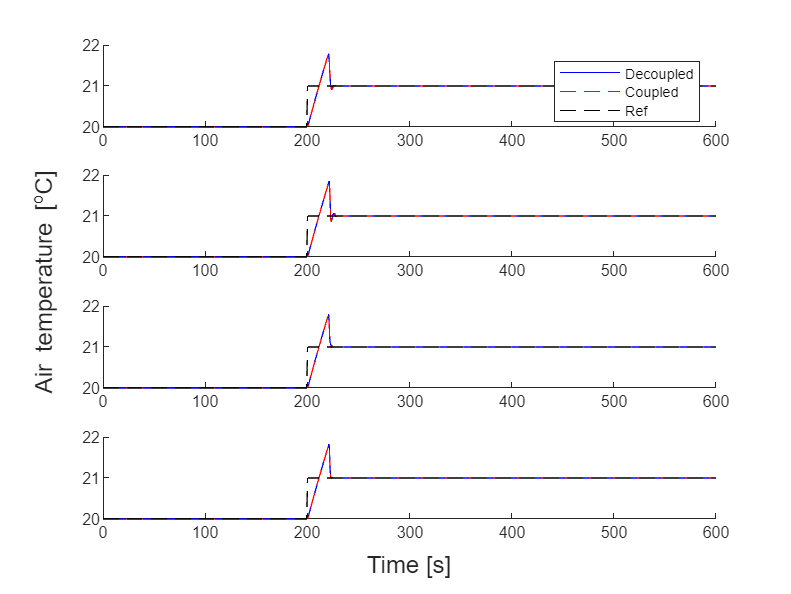


Ks = zeros(1,3,param.n);
for j=1:param.n
    Ks(1,2:3,j) = F_min(j,2*(j-1)+1:2*j);
end
param.ctrl.Ks = Ks;


[decoupledResults,coupledResults] = util.SimulateStep(param,"Output_Feedback",0);



% K = blkdiag(param.ctrl.Ks(:,:,1),param.ctrl.Ks(:,:,2),param.ctrl.Ks(:,:,3),param.ctrl.Ks(:,:,4));
K = blkdiag(param.ctrl.Ks(1,2:3,1),param.ctrl.Ks(1,2:3,2),param.ctrl.Ks(1,2:3,3),param.ctrl.Ks(1,2:3,4));

s = tf('s');
M = K * Cy/(s * eye(12) - (param.model.A + param.model.B * K * Cy) )*param.model.B;
hinfnorm(M)

ans = 1.9749


M2 = Ksf/(s * eye(12) - (param.model.A + param.model.B * Ksf) )*param.model.B;
hinfnorm(M2)

ans = 1.0120

eig(param.model.A + param.model.B * (1+(-1)) * K * Cy)

ans =          0
         0
         0
         0
   -4.0442
   -0.0312
   -0.0311
   -4.0059
   -0.0311
   -4.0059


eig(param.model.A + param.model.B * (1+(1)) * K * Cy)

ans =   -1.5303 + 6.4760i
  -1.5303 - 6.4760i
  -1.5191 + 3.8398i
  -1.5191 - 3.8398i
  -1.4079 + 5.6024i
  -1.4079 - 5.6024i
  -1.3645 + 5.0628i
  -1.3645 - 5.0628i
  -1.4449 + 0.0000i
  -1.1688 + 0.0000i
